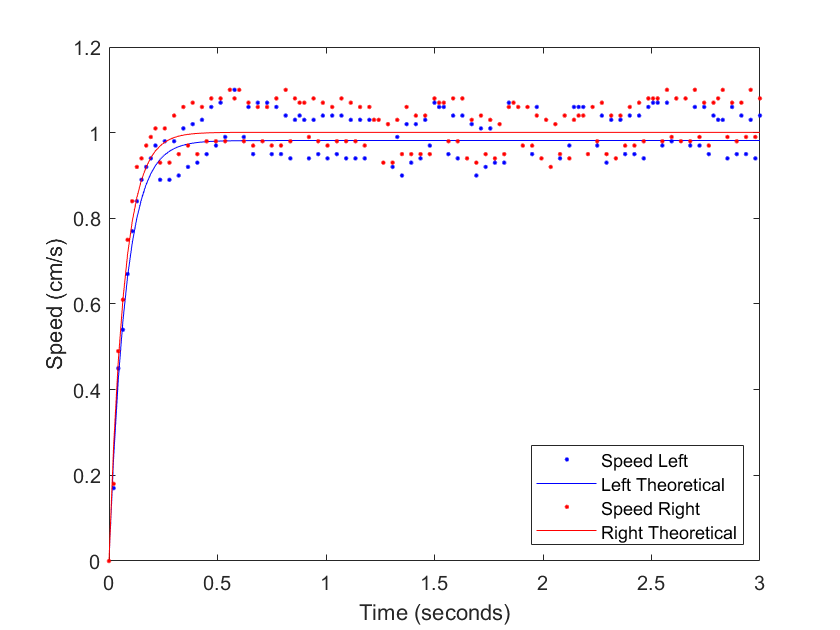

T = csvread('rocky_data_onground.csv');
time = linspace(0, 3, 141); % seconds
measured_speedL = T(:,1); % cm/s
measured_speedR = T(:,2); % cm/s

k_left = 0.003272;

clf;
tau_left = 0.07584;
plot(time, measured_speedL, 'b.'); hold on;
plot(time, 300*k_left-300*k_left*exp(-time./tau_left), 'b-');

k_right =  0.003336;
tau_right = 0.06813;
plot(time, measured_speedR, 'r.');
plot(time, 300*k_right-300*k_right*exp(-time./tau_right), 'r-');
xlabel('Time (seconds)')
ylabel('Speed (cm/s)')
legend('Speed Left', 'Left Theoretical', 'Speed Right', 'Right Theoretical', 'Location','southeast')